# Loading paths

ft_defaults()
bml_defaults()
format long


## Defining paths 


SUBJECT='DM1046';
SESSION = 'intraop';
TASK = 'ECoGeStim';
%PATH_DATASET = '/Volumes/Nexus4/DBS';
PATH_DATASET = 'Y:\DBS';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];
PATH_FIELDTRIP = [PATH_DER_SUB filesep 'fieldtrip'];

PATH_SRC = [PATH_DATASET filesep 'sourcedata'];
PATH_SRC_SUB = [PATH_SRC filesep 'sub-' SUBJECT];  
PATH_RIPPLE = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'ripple'];
PATH_ALHAOMEGA = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'alphaomega']; %path to neuroomega's mpx files.
PATH_ALHAOMEGA_MAT = [PATH_ALHAOMEGA]; %path to neuroomega's converted mat files.
PATH_AUDIO_DER = [PATH_DER_SUB filesep 'aec']; %path to acoustic echo cancelling folder
PATHS_AUDIO_SRC = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'audio');
PATHS_TASK = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'task');

% loading annotation tables
sync = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_sync.tsv']);
% sync.folder = strrep(sync.folder,'Y:\DBS',PATH_DATASET);
% sync.folder = strrep(sync.folder,'\',filesep);
sessions = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_sessions.tsv']);
runs = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_runs.tsv']);
channels = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_channels.tsv']);
%stable_MER = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_stable-MER.tsv']);

epoch = bml_annot_extend(runs(strcmp(runs.task,TASK) & strcmp(runs.session,SESSION),:),5,5);
epoch = epoch(~contains(epoch.comment,'test'),:) 

epoch = 3×18 table
    id      starts           ends            duration          session          task         run    session_day    time_starts    time_ends    audio    trellis     MER_side     MER_track     MER_depth      DBS_left      DBS_right       comment   
    __    ___________    ____________    ________________    ___________    _____________    ___    ___________    ___________    _________    _____    _______    __________    __________   

## Loading sessions from trellis

cfg=[];
cfg.epoch=epoch;
cfg.roi=sync(sync.filetype=="trellis.nf6",:);
cfg.electrode = channels(channels.filetype=="trellis.nf6",:);
cfg.electrode = cfg.electrode(cfg.electrode.duration > 0, :);
cfg.electrode.electrode = cfg.electrode.name;
[nf6, loaded_epoch] = bml_load_epoched(cfg);


 --- Loading epoch id 14 (1 of 3) --- 
electrode table has no chantype variable.
processing channel { 'hifreq 1' 'hifreq 2' 'hifreq 3' 'hifreq 4' 'hifreq 5' 'hifreq 6' 'hifreq 7' 'hifreq 8' 'hifreq 9' 'hifreq 10' 'hifreq 11' 'hifreq 12' 'hifreq 13' 'hifreq 14' 'hifreq 15' 'hifreq 16' 'hifreq 17' 'hifreq 18' 'hifreq 19' 'hifreq 20' 'hifreq 21' 'hifreq 22' 'hifreq 23' 'hifreq 24' 'hifreq 25' 'hifreq 26' 'hifreq 27' 'hifreq 28' 'hifreq 29' 'hifreq 30' 'hifreq 31' 'hifreq 32' 'hifreq 33' 'hifreq 34' 'hifreq 35' 'hifreq 36' 'hifreq 37' 'hifreq 38' 'hifreq 39' 'hifreq 40' 'hifreq 41' 'hifreq 42' 'hifreq 43' 'hifreq 44' 'hifreq 45' 'hifreq 46' 'hifreq 47' 'hifreq 48' 'hifreq 49' 'hifreq 50' 'hifreq 51' 'hifreq 52' 'hifreq 53' 'hifreq 54' 'hifreq 55' 'hifreq 56' 'hifreq 57' 'hifreq 58' 'hifreq 59' 'hifreq 60' 'hifreq 61' 'hifreq 62' 'hifreq 63' 'hifreq 64' 'hifreq 129' 'hifreq 130' 'hifreq 131' 'hifreq 132' 'hifreq 133' 'hifreq 134' 'hifreq 135' 'hifreq 136' 'hifreq 137' 'hifreq 138' 'hifreq 


if ~isfield(nf6,'sampleinfo')
    %adding sample info if missing. Assuming contiguity.
    s = cumsum(cellfun(@(x) size(x,2),nf6.time,'UniformOutput',true));
    nf6.sampleinfo = [[0, s(1:(end-1))]' + 1, s'];
end

%downsampling to 1kHz
cfg=[]; 
cfg.lpfilter='yes'; 
cfg.lpfreq=500; 
cfg.lpfilttype = 'but'; 
cfg.lpfiltord = 6; %sixth order butterworth lowpass filter
cfg.lpfiltdir = 'twopass'; %for zero lag
cfg.lpinstabilityfix = 'no';
cfg.lpfiltwintype = 'hamming';
cfg.trackcallinfo = false;
cfg.showcallinfo = 'no';
nf6_f = ft_preprocessing(cfg,nf6);

preprocessing
preprocessing trial 3 from 3




cfg=[];
cfg.resamplefs = 1000;
nf6_1kHz = ft_resampledata(cfg,nf6_f)

the input is raw data with 160 channels and 3 trials


the call to "ft_selectdata" took 0 seconds
resampling data


resampling data in trial 3 from 3

original sampling rate = 7500 Hz
new sampling rate = 1000 Hz
the call to "ft_resampledata" took 21 seconds


nf6_1kHz = struct with fields:
    fsample: 1000
        hdr: [1×1 struct]
      trial: {[160×38005 double]  [160×34605 double]  [160×238273 double]}
       time: {1×3 cell}
      label: {160×1 cell}
        cfg: [1×1 struct]


## loading ns5

cfg=[];
cfg.epoch=epoch;
cfg.roi=sync(sync.filetype=="trellis.ns5",:);
cfg.electrode = channels((channels.filetype=="trellis.ns5") & (ismember(channels.type,{'PD','MISC','AUDIO'})),:);
cfg.electrode.electrode = cfg.electrode.name;
ns5 = bml_load_epoched(cfg);


 --- Loading epoch id 14 (1 of 3) --- 
electrode table has no chantype variable.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
processing channel { 'analog 1' 'analog 2' 'analog 29' 'analog 30' }
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.

 --- Loading epoch id 15 (2 of 3) --- 
electrode table has no chantype variable.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicros


ns5_1kHz = bml_conform_to(nf6_1kHz,ns5);

low-pass filtering slave [30000.000000 Hz] to half the master's sampling rate [500.000000 Hz], using 6th order Butterworth


preprocessing
preprocessing trial 3 from 3

the input is raw data with 4 channels and 3 trials


original sampling rate = 3.000000e+04 Hz
new sampling rate = 1.000000e+03 Hz


ns5_7k5Hz = bml_conform_to(nf6,ns5);

low-pass filtering slave [30000.000000 Hz] to half the master's sampling rate [3750.000000 Hz], using 6th order Butterworth


preprocessing
preprocessing trial 3 from 3

the input is raw data with 4 channels and 3 trials


original sampling rate = 3.000000e+04 Hz
new sampling rate = 7.500000e+03 Hz


## appending data

cfg=[];
cfg.appenddim  = 'chan';
D = ft_appenddata(cfg,  nf6_1kHz, ns5_1kHz);

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 0 seconds



%creating header
hdr=[];
hdr.Fs=bml_getFs(D);
hdr.nChans=length(D.label);
hdr.nSamples=sum(cellfun(@(x)size(x,2),D.trial));
hdr.nSamplesPre=0;
hdr.nTrials=length(D.trial);
hdr.label=D.label;
hdr.chantype=strtok(D.label,'_');
hdr.chantype=hdr.chantype(:,1);
hdr.chanunit=bml_map(hdr.label,channels.name,channels.units,'unknown'); 
D.hdr=hdr;


cfg=[];
cfg.appenddim  = 'chan';
D_7k5Hz = ft_appenddata(cfg,  nf6, ns5_7k5Hz);

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 2 seconds



%creating header
hdr=[];
hdr.Fs=bml_getFs(D_7k5Hz);
hdr.nChans=length(D_7k5Hz.label);
hdr.nSamples=sum(cellfun(@(x)size(x,2),D_7k5Hz.trial));
hdr.nSamplesPre=0;
hdr.nTrials=length(D_7k5Hz.trial);
hdr.label=D_7k5Hz.label;
hdr.chantype=strtok(D_7k5Hz.label,'_');
hdr.chantype=hdr.chantype(:,1);
hdr.chanunit=bml_map(hdr.label,channels.name,channels.units,'unknown'); 
D_7k5Hz.hdr=hdr;


## Saving the data

save([PATH_FIELDTRIP filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_ft-raw.mat'],'D','loaded_epoch','-v7.3');
save([PATH_FIELDTRIP filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_ft-raw-7k5Hz.mat'],'D_7k5Hz','loaded_epoch','-v7.3');

Save for each run-id, too. This is the same data as above, but split up into runs. 

assert(height(epoch)==length(D.trial)) % ensure
D_all = D; 
for itrial = 1:height(epoch)
    cfg = []; 
    cfg.trials = itrial; 
    D = ft_selectdata(cfg, D_all); 
    save([PATH_FIELDTRIP filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_run-' sprintf('%02d', epoch.run(itrial)) '_ft-raw.mat'],'D','loaded_epoch','-v7.3');
end

the call to "ft_selectdata" took 0 seconds


the call to "ft_selectdata" took 0 seconds


the call to "ft_selectdata" took 0 seconds


## Saving stimulation events as annots

cfg=[];
cfg.roi = sync(sync.filetype=="trellis.nev",:);
stim_events = bml_annot_read_stim_nev(cfg);

Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/latest">GitHub NPMK Page</a> to get the latest version.
Checking for a new version of NPMK...
A new version of NPMK may be available.
Please visit <a href="https://github.com/BlackrockMicrosystems/NPMK/releases/l

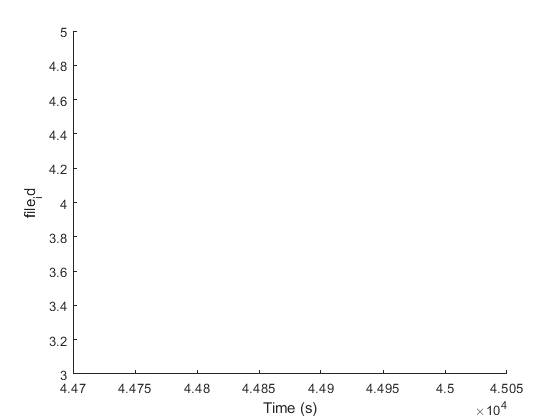

stim_events = bml_annot_filter(stim_events,epoch);
bml_annot_write_tsv(stim_events,[PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_stimulation-pulses.tsv']);

cfg=[];
cfg.criterion = @(x) (abs(max(x.ends)-min(x.starts))<0.1);
stim_events_cons = bml_annot_consolidate(cfg,stim_events);
bml_annot_write_tsv(stim_events_cons,[PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK  '_stimulation-bursts.tsv']);

cfg=[];
cfg.y = 'file_id'; 
figure();
bml_annot_plot(cfg,stim_events_cons)